%% Default analysis parameters
anProp.nMobile = 1;     % number of diffusive populations
anProp.immBool = 1;     % presence or absence of stationary population
anProp.tFrame = .04;    % camera integration time in seconds
anProp.pixSize = .049;  % pixel size in microns
anProp.maxTau = 10;      % maximum time lag in frames
anProp.confBool = 0;    % confined or unconfined diffusion
% anProp.globBool = 0;    % global or local cpd fit
anProp.overBool = 0;    % use overlapping or non-overlapping displacements?
anProp.plotBool = 0;    % plot output or not
anProp.dim = 2;         % 1d or 2d diffusion analysis
anProp.whichDim = 1;    % for 1d diffusion, which dimension to consider
anProp.rotAngle = pi/3; % for 1d diffusion, clockwise angle to rotate the trajectory
anProp.bootNum = 40;   % number of bootstraps

% time lag domain in seconds
tau = (1:anProp.maxTau)'*anProp.tFrame;

% partial 2d cpd function
c2=@(x,y,p)p*exp(-x./y);

% partial 1d cpd function
c1=@(x,y,p)p*erf(sqrt(x./2/y));

% 2d confined msd function
m2=@(t,p)4*p(1)*t+p(2);

% 1d unconfined msd function
m1=@(t,p)2*p(1)*t+p(2);

% gaussian
nY = @(m,v,x)exp(-(x-m).^2/2/v)/sqrt(2*pi*v);

opts = optimset('Display','off');

%% calculate and accumulate squared step sizes
for kk=1:numel(tr)
    trackNums = unique(tr{kk}(:,1))';
    
    if ~isempty(trackNums)
        for ii = trackNums
            tracks = tr{kk}(tr{kk}(:,1)==ii,[2,4,5]);
            
            % fill in the time holes with nans
            fixedTrack = nan(max(tracks(:,1)),size(tracks,2));
            fixedTrack(tracks(:,1),:) = tracks;
            
            % remove leading nans
            fixedTrack(1:find(all(isnan(fixedTrack),2)==0,1,'first')-1,:) = [];
            
            nLocs = size(fixedTrack,1);
            for jj=1:anProp.maxTau
                if anProp.overBool
                    indvec1=jj+1:nLocs;
                    indvec2=1:nLocs-jj;
                elseif ~anProp.overBool
                    indvec2=1:jj:nLocs;
                    indvec1=indvec2(1:end-1);
                    indvec2=indvec2(2:end);
                end
                
                % calculate squared step sizes
                if anProp.dim == 2
                    allSqSteps{kk,ii,jj}=nansum( (fixedTrack(indvec1,[2,3]) - ...
                        fixedTrack(indvec2,[2,3])).^2, 2);
                elseif anProp.dim == 1
                    allSqSteps{kk,ii,jj}=(fixedTrack(indvec1,[2,3]) - ...
                        fixedTrack(indvec2,[2,3])).^2;
                end
            end
        end
    end
end

if anProp.dim == 2
    sqSteps=cell(anProp.maxTau,1);
    for ii=1:anProp.maxTau
        wSteps = cat(1,allSqSteps{:,:,ii});
        sqSteps{ii}=sort(wSteps(wSteps > eps));     % nansum puts zeros where there were nans
    end
    oRanks=cellfun(@(x)linspace(0,1,numel(x))',sqSteps,'uniformoutput',0);
else
    rMat = [cos(anProp.th),-sin(anProp.th);sin(anProp.th),cos(anProp.th)];
    
    sqSteps=cell(anProp.maxTau,1);
    for ii=1:anProp.maxTau
        y=sort(cat(1,allSqSteps{:,ii}));
        rPoints=y*rMat;
        sqSteps{ii}=rPoints(:,anProp.whichDim);
    end
    
    oRanks=cellfun(@(x)linspace(0,1,size(x,1))',sqSteps,'uniformoutput',0);
end
nSteps = cellfun(@numel,sqSteps,'uniformoutput',0);
nTotal = sum(cat(1,nSteps{:}));

%% GLOBAL FITTING
anProp.globBool = 1;

% fitting function selection
funFinds = cpdFunFinder(anProp)

funFinds =     cpdFun: @(x,y,p)1-c2(x,y+p(4),p(3))-c2(x,p(4),1-p(3))
    msdFun: @(tau,p)m2(tau,p(1:2))
    pStart: {[0.1000 0.0100 0.8000 0.0100]}
    bounds: {[0 0 0 0]  [Inf Inf 1 Inf]}
       dID: 1
       aID: 3

cpdFun = funFinds.cpdFun;
msdFun = funFinds.msdFun;
pStart = funFinds.pStart;
bounds = funFinds.bounds;
dID = funFinds.dID;
aID = funFinds.aID;

linCell=@(x)cat(1,x{:});
fHandle=@(p,tau,sqSteps,ranks)linCell(...
    cellfun(@(x,y)x-y,...
    cellfun(@(x,y)cpdFun(x,y,p),...
    sqSteps,num2cell(msdFun(tau,p),2),'uniformoutput',0),...
    ranks,'uniformoutput',0));
eHandle=@(p,tau,sqSteps)cellfun(@(x,y)cpdFun(x,y,p),...
    sqSteps,num2cell(msdFun(tau,p),2),'uniformoutput',0);

% all data
y = cellfun(@(x)x*anProp.pixSize.^2,sqSteps,'uniformoutput',0);
[f1,~,r1] = lsqnonlin(@(p)fHandle(p,tau,y,oRanks),...
    pStart{1},bounds{1},bounds{2},opts);

% bootstrapped data
fParamsG = zeros(numel(pStart{1}),anProp.bootNum);
residsG = zeros(nTotal,anProp.bootNum);
parfor kk = 1:anProp.bootNum
    % converts track positions from pixels to microns and resamples at the same
    % time
    y=cellfun(@(x,y)sort(x(randsample(y,y,1))*anProp.pixSize.^2),sqSteps,nSteps,...
        'uniformoutput',0);
    
    [fParamsG(:,kk),~,residsG(:,kk)] = lsqnonlin(@(p)fHandle(p,tau,y,oRanks),...
        pStart{1},bounds{1},bounds{2},opts);
end

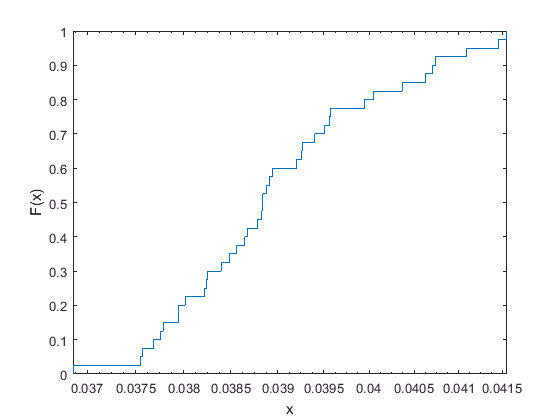

dOut = fParamsG(dID,:);
aOut = fParamsG(aID,:);

for ii = 1:numel(dID)
    ecdf(dOut(ii,:)); hold all
end; hold off; set(gca,'xscale','log')

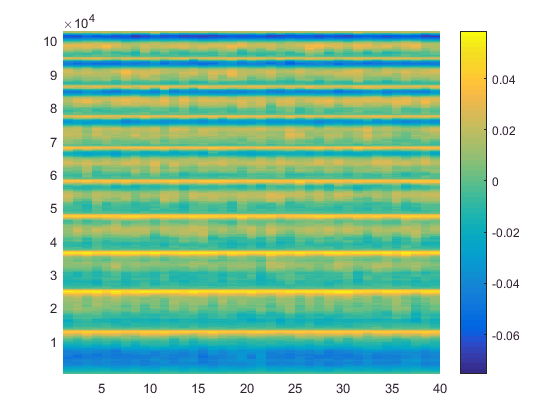


pcolor(residsG); shading flat; colorbar


% calculate likelihoods
lLike = zeros(anProp.maxTau,numel(dID));
for ii = 1:anProp.maxTau
    for jj = 1:numel(dID)
        lLike(ii,jj) = sum(log(nY(0,4*f1(dID(jj))*tau(ii),sqrt(y{ii}))))*nSteps{ii}/nTotal;
    end
end

lLike = sum(lLike,1);

%     BIC = nTotal*log(mean(resids.^2,1)) + numel(pStart{1})*log(nTotal);
BIC2 = -2*lLike + numel(pStart{1})*log(nTotal)

BIC2 = -9.3901e+03

%     BIC2 = nTotal*log(mean(r1.^2,1)) + numel(pStart{1})*log(nTotal);


%% LOCAL FITTING
anProp.globBool = 0;

% fitting function selection
funFinds = cpdFunFinder(anProp)

funFinds =     cpdFun: @(x,p)1-c2(x,p(1)+p(2),p(3))-c2(x,p(2),1-p(3))
    msdFun: @(tau,p)m2(tau,p(1:2))
    pStart: {[0.1000 0.8000 0.5000]  [0.1000 0.0100]}
    bounds: {[0 0 0]  [Inf Inf 1]  [0 -Inf]  [Inf Inf]}
       dID: 1
       aID: [1x0 double]

cpdFun = funFinds.cpdFun;
msdFun = funFinds.msdFun;
pStart = funFinds.pStart;
bounds = funFinds.bounds;
dID = funFinds.dID;
aID = funFinds.aID;

cpdLB = bounds{1};
cpdUB = bounds{2};
msdLB = bounds{3};
msdUB = bounds{4};
cpdStart = pStart{1};
msdStart = pStart{2};

y=cellfun(@(x,y)sort(x(randsample(y,y,1))*anProp.pixSize.^2),sqSteps,nSteps,...
    'uniformoutput',0);
for ii = 1:anProp.maxTau
    for jj = 1:anProp.nMobile
        cpdStart(ii,jj) = mean(y{ii})/10^(jj-1);
    end
end

fParams1a = zeros(numel(pStart{1}),anProp.maxTau,anProp.bootNum);
aOut = zeros(numel(aID),anProp.maxTau,anProp.bootNum);
residsL = zeros(nTotal,anProp.bootNum);
parfor kk = 1:anProp.bootNum
    fParams1 = zeros(numel(cpdStart(1,:)),anProp.maxTau);
    fParams2 = zeros(numel(msdStart),anProp.nMobile);
    
    y=cellfun(@(x,y)sort(x(randsample(y,y,1))*anProp.pixSize.^2),sqSteps,nSteps,...
        'uniformoutput',0);
    
    % fit the cpd curves to get the msd values
    r = [];
    for mm=1:anProp.maxTau
        [fParams1(:,mm),~,rTemp] = lsqcurvefit(@(p,x)cpdFun(x,p),...
            cpdStart(mm,:),y{mm},oRanks{mm},cpdLB,cpdUB,opts);
        r = cat(1,r,rTemp);
    end
    residsL(:,kk) = r;
    
    fParams1a(:,:,kk) = fParams1;
    
    % fit msds to get diffusion coefficients
    for mm = 1 : anProp.nMobile
        %         fParams2(:,mm)=lsqcurvefit(@(p,x)msdFun(x,p),msdStart,tau,fParams1(mm,:)',...
        %             msdLB,msdUB,opts);
        fParams2(:,mm) = lsqnonlin(@(p)(msdFun(tau,p)-fParams1(mm,:)') .* [nSteps{:}]'/nTotal,...
            msdStart,msdLB,msdUB,opts);
        %             resids{2,ii} = msdFun(tau,fParams(ii,:)) - msds(ii,:)';
    end
    dOut(:,kk) = fParams2(dID,:);
    
    if numel(aID) > 0
        aOut(:,:,kk) = fParams1(aID,:);
    end
end

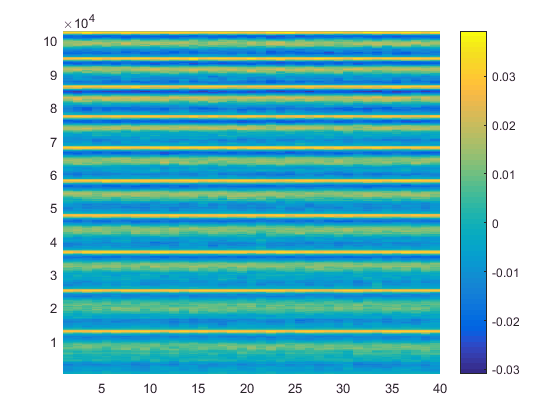

pcolor(residsL); shading flat; colorbar

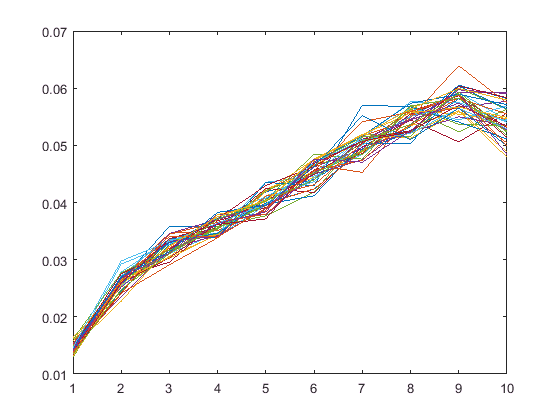

for ii = 1:anProp.bootNum
    plot(fParams1a(1:anProp.nMobile,:,ii)'); hold all
end; hold off


% calculate BIC
%     mean(-log(nY(mean(x),var(x),x)))
BIC = nTotal*log(residsL.^2) + anProp.maxTau * numel(pStart{1})*log(nTotal);

%% plot fits
if anProp.plotBool
    %     figure
    %     if anProp.globBool
    %         fRes = eHandle(fParams(:,1),tau,y);
    %         for ii = 1:anProp.maxTau
    %             subplot(1,anProp.maxTau,ii)
    %             plot(y{ii},cat(2,oRanks{ii},fRes{ii}),'.')
    %             set(gca,'xscale','log')
    %         end
    %
    %     elseif ~anProp.globBool
    %         for ii = 1:anProp.maxTau
    %             subplot(1,anProp.maxTau,ii)
    %             plot(y{ii},cat(2,oRanks{ii},cpdFun(y{ii},fParams1a(1,ii,:))),'.')
    %             set(gca,'xscale','log')
    %         end
    %     end
    subplot(131)
    for ii=1:size(dOut,1)
        %     subplot(1,numel(dID),ii)
        ecdf(dOut(ii,:)); hold all
    end; hold off
    xlabel('d in microns^2/s')
    set(gca,'xscale','log')
    
    subplot(132)
    for ii = 1:size(aOut,1)
        ecdf(aOut(ii,:)); hold all
    end; hold off
    xlabel('relative population amplitudes')
    
    subplot(133)
    for ii = 1:anProp.bootNum
        plot(resids(:,ii)); hold all
    end; hold off
end